# MATLABを用いたポルトガル発祥ワイン"ヴィーニョ・ヴェルデ

# (Vinho Verde)"の美味しさを決める条件の発見

### 所属クラス：C3,氏名：山野 元久, 学籍番号：s1320112,

## 1. 導入(Introduction)

　ヴィーノ・ヴェルデとは、ポルトガル北西部にあるミーニョ地方で生産されるワインの一種である[1]。ポルトガル語で「Vinho」はワイン、「Verde」は緑を意味している。この由来にはいくつか説があり、[2]では厳しい冬期にも非常に緑鮮やかな色に実るからそう名付けられたと解説している。今回は、ダウンロードしたオープンデータセットから、そんなヴィーニョ・ヴェルデ製品ごとの成分のばらつき、各製品に対する品質の評価を用いて、可能な限りの手法により、データの可視化を試みたい。特に、ワインの品質の良さを決定づけるのは何なのかについて解明してみたい。

## 2. データ(Data)

　　この研究の為に用いたデータセット"Tabular representation of wine quality dataset"の詳細は以下の通りである。

- 名前：Tabular representation of wine quality dataset

- 制作者：Karanth, Manohar

- データ取得元URL：https://zenodo.org/records/4090212

- ライセンス：Creative Commons Attribution 4.0 International

- サイト名：Zenodo

　　各列の概要：

- 　　fixed acidity：固定酸度。単位はg/dm³。

- 　　volatile acidity：揮発性酸度。単位はg/dm³。

- 　　citric acid：クエン酸。単位はg/dm³。

- 　　residual sugar：残留糖分。単位はg/dm³

- 　　chlorides：塩化物。単位はg/dm³。

- 　　free sulfur dioxide：遊離二酸化硫黄。単位はmg/dm³。

- 　　total sulfur dioxide：総二酸化硫黄。単位はmg/dm³。

- 　　density：密度。単位はg/cm³。

- 　　pH：pH値。

- 　　sulphates：亜硫酸塩。単位はg/dm³。

- 　　alcohol：アルコール度数。単位は％。

- 　　quality：品質評価。正の整数をとる。

　　APA：Karanth, M. (2020). Tabular representation of wine quality dataset [Data set]. Zenodo. https://doi.org/10.5281/zenodo.4090212

## 3. 手法(Method)

　まず、readable関数を用いて、csvデータをインポートする。

clf;
warnState = warning('off', 'MATLAB:table:ModifiedAndSavedVarnames');
dataset = readtable('WineQualityRed.csv');
warning(warnState);

　データの全容を理解するため、それぞれの列について平均値、中央値、を求めてみる。

%%1行目が平均値を、2行目が中央値をそれぞれ示している%%
%%一気に出力するとPDF出力時に見えなくなるため二つに分けた。%%
data_summary1 = [mean(dataset(:,1:end/2));median(dataset(:,1:end/2))];
data_summary2 = [mean(dataset(:,end/2+1:end));median(dataset(:,end/2+1:end))];
format short
disp(data_summary1);

    fixedAcidity    volatileAcidity    citricAcid    residualSugar    chlorides    freeSulfurDioxide
    ____________    _______________    __________    _____________    _________    _________________

       8.3196           0.52782         0.27098         2.5388        0.087467          15.875      
          7.9              0.52            0.26            2.2           0.079              14      



disp(data_summary2);

    totalSulfurDioxide    density      pH      sulphates    alcohol    quality
    __________________    _______    ______    _________    _______    _______

          46.468          0.99675    3.3111     0.65815     10.423      5.636 
              38          0.99675      3.31        0.62       10.2          6 



　加えて、データ全体の傾向を相関行列によって整理し、ヒートマップを用いて確認する。

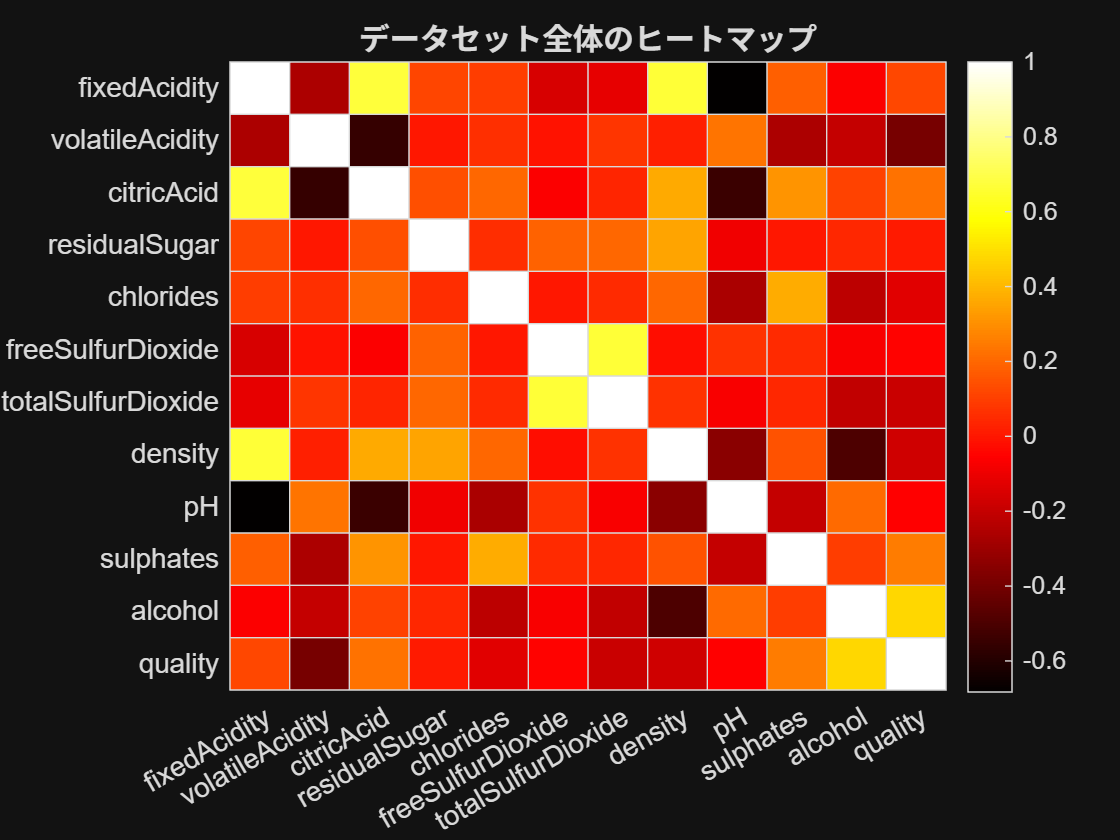

cor = corrcoef(dataset.Variables);
dataName = string(dataset.Properties.VariableNames);
h = heatmap(dataName,dataName,cor);
colormap(h, hot)
title('データセット全体のヒートマップ')

　ここで、相関係数が0.668最も高い[固定酸度, 密度]、相関係数-0.683で最も低い[固定酸度, pH値]について散布図で詳しく観察する。

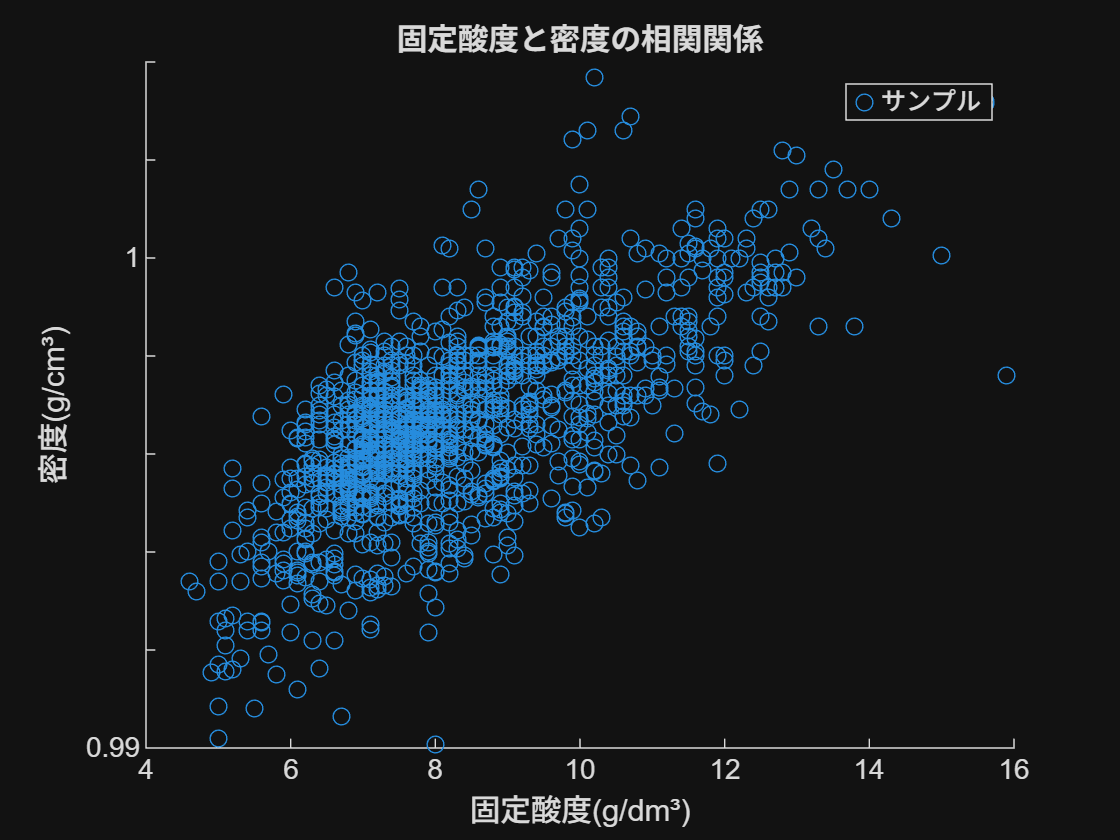


scatter(dataset(:,1).Variables ,dataset(:,8).Variables)
title("固定酸度と密度の相関関係")
xlabel("固定酸度(g/dm³)")
ylabel("密度(g/cm³)")
yticklabels({0.99,[], [], [], [], 1})
legend("サンプル")

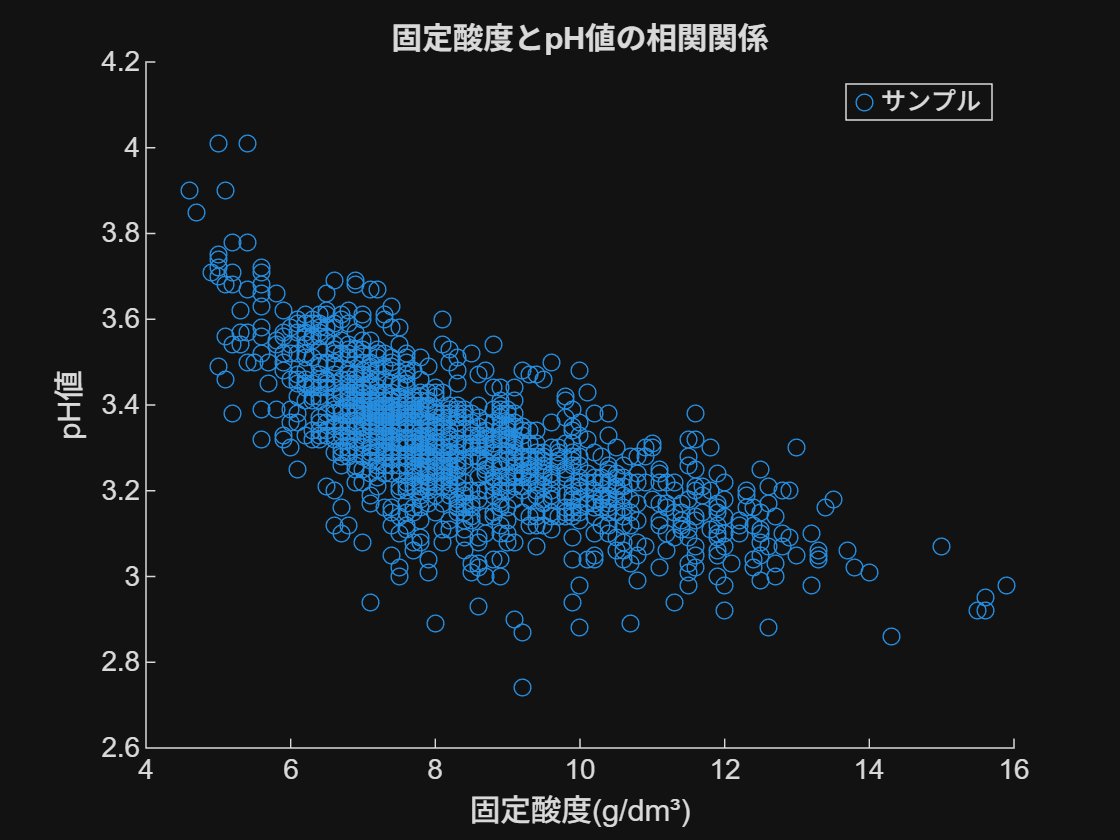


scatter(dataset(:,1).Variables,dataset(:,9).Variables)
title("固定酸度とpH値の相関関係")
xlabel("固定酸度(g/dm³)")
ylabel("pH値")
legend("サンプル")

　ここからは、説明変数の行列と目的変数の行列を分けておく。

ex_variable = dataset( :, 1 : end - 1); 
quality = dataset(:, 12).Variables;

　この12の配列に分けた中で、qualityのみは科学的な単位に基づかない特殊なデータであるため、ヒストグラムとしてプロットし、全体の傾向を確認する。

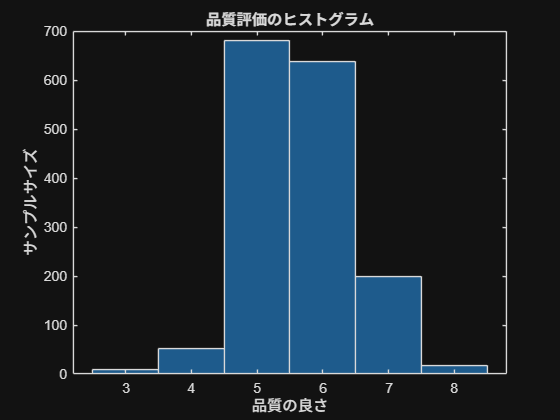

%%histogram関数によって可視化する。
histogram(quality)
title('品質評価のヒストグラム')
xlabel('品質の良さ')
ylabel('サンプルサイズ')

　ヒストグラムからqualityの値が3~8の間の整数を取る変数であることを確認した上で、次に個々の項目同士の関係性を比較していきたい。ヒートマップにてqualityと相関関係が顕著な上位の4項目(alcohol, sulphates, citicAcid, fixed acidity)に対して、個別に箱ひげ図を用い、全体の傾向と外れ値の有無等、より深い関係性を観察する。今回、関係性を調べるうえで散布図でなく箱ひげ図を用いたのは、qualityが離散的なデータだからである。散布図はx,yの値が連続であることを前提として作られているため、今回のケースでは不都合と判断した。

boxchartmatrix1 = Table[Pick[body[[All, 11]],body[[All, 12]] == i],{i, 3, 8}]

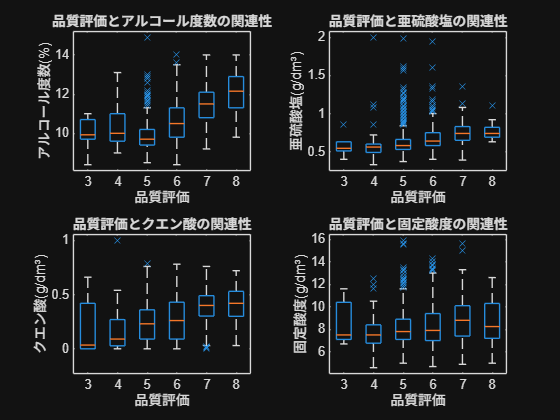

%%tiledlayoutを用いて4つの箱ひげ図を描写
figure;
tiledlayout(2,2);

warnState = warning('off', 'stats:boxplot:BadObjectType');

nexttile;
alcohol = dataset(:,11).Variables;
boxplot(alcohol, quality, 'Symbol','x')
xlabel("品質評価")
ylabel("アルコール度数(%)")
title("品質評価とアルコール度数の関連性")

nexttile
sulphates = dataset(:,10).Variables;
boxplot(sulphates, quality, 'Symbol','x')
xlabel("品質評価")
ylabel("亜硫酸塩(g/dm³)")
title("品質評価と亜硫酸塩の関連性")

nexttile
cit_ac = dataset(:,3).Variables;
boxplot(cit_ac, quality, 'Symbol','x')
xlabel("品質評価")
ylabel("クエン酸(g/dm³)")
title("品質評価とクエン酸の関連性")

nexttile
fix_ac = dataset(:,1).Variables;
boxplot(fix_ac, quality, 'Symbol','x')
warning(warnState);
xlabel("品質評価")
ylabel("固定酸度(g/dm³)")
title("品質評価と固定酸度の関連性")

　最後に、fitctreeを用いて、このモデルの背後にある品質評価が変動するルールについて調べる。

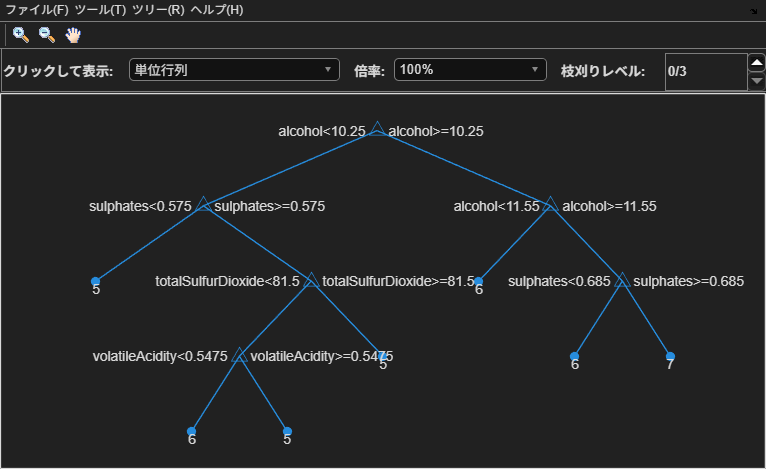

%%第1引数が説明変数、第2引数が目的変数である。
model = fitctree(ex_variable, quality);
%%このメソッドによって出力されるノードが膨大なため、PDFでは出力をキャンセルしている。
view(model, 'Mode','text');
%モデルを最低限判読可能なレベルで可視化するためその解像度を下げている。
model_p = prune(model,'level', 23);
view(model_p, 'Mode', 'graph')

　上記の木の無向グラフは、11個の説明変数に基づいてどのような条件を辿るとそれぞれの評価が得られるのかを視覚的に示している視覚化しやすいように木を単純化しているが、本来の形は"view(model, 'Mode','text')"で示されている通りより一層複雑である。

　ここから、品質評価の最高指標である評価8の葉を探し、そこから親のノードを辿ることによって最高品質のワインが得られる条件を探る。

eight_grade = find((~model.IsBranchNode) & strcmp(model.NodeClass, '8'));
for i=1:1:3
    disp(['ルートの' num2str(i) '回目：' ])
    node = eight_grade(i)
  while node ~= 1
    node = model.Parent(node)
  end
end

ルートの1回目：


node = 149

node = 94

node = 52

node = 28

node = 15

node = 7

node = 3

node = 1

ルートの2回目：


node = 150

node = 95

node = 52

node = 28

node = 15

node = 7

node = 3

node = 1

ルートの3回目：


node = 153

node = 97

node = 53

node = 28

node = 15

node = 7

node = 3

node = 1

この3つのルートに対し、"view(model, 'Mode','text')"で得た条件を当てはめ、以下にまとめた。この3制約のいずれかを満たすものが品質評価において最も高く評価されたという事になる。

- `alcohol>=11.55, sulphates>=0.685, 9.5>freeSulfurDioxide, 0.35>volatileAcidity, density>=0.99625`

- `alcohol>=11.55, 0.73>sulphates>=0.685, 9.5>freeSulfurDioxide,  volatileAcidity>=0.35`

- `alcohol>=11.55, 18.5>freeSulfurDioxide>=9.5, sulphates>=0.695, volatileAcidity>=0.8425`

## 4. 結果(Result)

　3.手法(Method)にて視覚化したデータの全体的な傾向として、まず第1に評価指標を決定づけるファクターとして、決定的である単一の変数は存在しなかった。最終的に二分木で作成したモデルでも、良い評価を得るためには、複数のパラメータ間の精密な協調が必要である。

　データの中央値、平均値が隔たることはなく、記録されているデータの分布に大きな歪みがないものだと伺える。ただし、総二酸化硫黄(total sulfur dioxide)については各項目の中で一番平均値と中央値の差が大きかった。つまり、総二酸化硫黄については他と比較して右に裾が長い分布なのだと言える。

　ヒートマップでは、[固定酸度, 密度]、[固定酸度,クエン酸]、[遊離二酸化硫黄, 総二酸化硫黄]において相関係数0.5以上の正の相関が 、[固定酸度,pH値]、[クエン酸, 揮発性酸度]、[クエン酸, pH値]において相関係数-0.5以上の負の相関が見られた。また、品質評価と最も正の相関性の高い項目がアルコール度数で反対に負の相関が最も強いのは揮発性酸度だった。[固定酸度, 密度]と[固定酸度, pH値]における散布図をみると、その傾向がはっきりとわかる。

　品質評価のヒストグラムを作ることで、品質の評価が3から8までの整数であることが分かった。品質評価の最頻値は5である。ヒストグラムの形が正規分布のようになっており、最頻値から遠ざかると、その分該当するサンプルの数も減少する。

　アルコール度数、亜硫酸塩、クエン酸、固定酸度に対する品質評価の箱ひげ図では、特にアルコール度数、クエン酸は良い品質のものほど中央値と四分位数がより高い値を取る傾向があった。亜硫酸塩においても、わずかに含有量が上がると品質評価も向上していることが中央値の変動からわかる。一方で、固定酸度についてはそうした顕著な特徴は見られなかった。また、亜硫酸塩と固定酸度はグラフにおいて青いバツで示される外れ値を多く持っている。外れ値の量は特に5や6といったデータ数が多い評価値により多く見られた。クエン酸と亜硫酸塩について、最低値は品質評価の値によってあまり変動しなかった。

　fitctree()関数を用いた木構造モデルにおいては、3.手法(Method)内で求めた3つの制約のうちどれかを満たすことで品質評価8に近づけることがわかった。この制約の中で共通しているのはアルコール度数が11.55%以上であること。硫酸塩が0.685g/dm³以上であることの2点である。固定酸度は9.5g/dm³を境に条件が設けられている。揮発性酸度はすべてのパターンにおいて、条件の一部となっているが、境となっている値にはばらつきがある。

## 5. 議論/考察(Discuss)

　5.結果(Result)より品質の良いと評価されるワインには一定以上のアルコール度数、硫酸塩が必要であることが分かった。このような結果が出た要因には、この2つの物質がワインの風味を決定づける基本的な役割を果たしているからだといえる。アルコールや亜硫酸塩といった物質は水分内に含まれる微生物のはたらきを抑えることができる。これらを十分に含んだワインは試飲時に微生物や細菌によって風味が損なわれることを未然に防ぐことができるため、品質の良いワインにとって必要な条件になったのだと考える。

## 6. 結論(Conclusion)

　以上より、ヴィーニョ・ヴェルデ (Vinho Verde)の品質を決定づける重要な要素について、得たデータをグラフと木構造によって可視化し、求めた。11の要素が相互に影響しあい、結果的に複雑な過程を経て品質を決定づけており、特にその中でもアルコール度数と亜硫酸塩のパラメータが重要である。約1600のサンプルサイズから詳細に人間のワインに対する感性を可視化し定量的に求めることで、関係性と特徴が見られた。

## 7. 参照元(References)

- [1]株式会社アカデミー・デュ・ヴァン："ヴィーニョ・ヴェルデとは？爽やかな気分を味わえるポルトガルワイン",ACADEMIE DU VIN Blog, https://www.adv.gr.jp/blog/vinho-verde/, 2025年10月25日参照, 2020年

- [2]Wines of Portugal：”Wine Regions Vinho Verde”, Wines of Portugal, [https://winesofportugal.com/en/discover/wine-regions/vinho-verde/,](https://winesofportugal.com/en/discover/wine-regions/vinho-verde/,) 2025年10月25日参照, 2021年